internal.matlab.desktop.commandwindow.executeCommandForUser('addpath ''C:/Users/Manavjeet Singh/Git/Localization-simulation/SFSDP/SFSDP/subprograms''')
internal.matlab.desktop.commandwindow.executeCommandForUser('addpath ''C:/Users/Manavjeet Singh/Git/Localization-simulation/SFSDP/SFSDP/sdpam7-windows''')
internal.matlab.desktop.commandwindow.executeCommandForUser('addpath ''C:/Users/Manavjeet Singh/Git/Localization-simulation/SFSDP/SFSDP/examples''')

distanceMatrix0= [0, 0.219579, 0.414739, 0.501646, 0.756645, 0, 0; 0, 0, 0.356155, 0.629003, 0.471282, 0, 0; 0, 0, 0, 0, 0, 0.647147, 0.468894]

distanceMatrix0 =          0    0.2196    0.4147    0.5016    0.7566         0         0
         0         0    0.3562    0.6290    0.4713         0         0
         0         0         0         0         0    0.6471    0.4689


## sDim = 2, noOfSensors = 3, noOfAnchors = 4
## the number of dist. eq. between two sensors  = 3
## the number of dist. eq. between a sensor & an anchor = 6
## the min., max. and ave. degrees over sensor nodes = 4, 4,   4.00
## +0.0000e+00 <= x(1) <= +1.0000e+00
## +0.0000e+00 <= x(2) <= +1.0000e+00
## the max. radio range = 6.7082e-01, the estimated noisy factor = 8.3330e-02


xMatrix0 =     0.3000    0.3000    0.7000         0         0    1.0000    1.0000
    0.4000    0.6000    0.6000         0    1.0000         0    1.0000



A modified version of FSDP (Biswas and Ye)
Sunyoung Kim, Masakazu Kojima, Hayato Waki and Makoto Yamashita
Version 1.22, January 2010



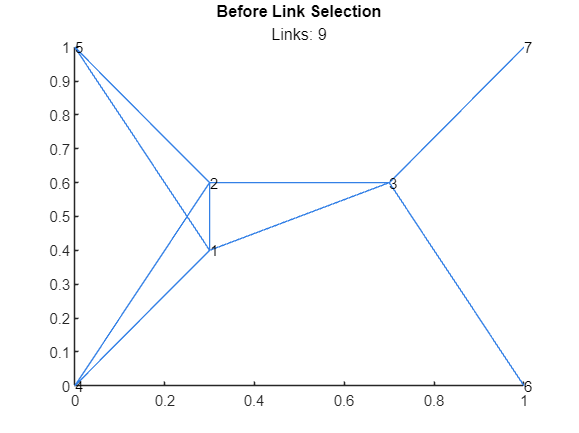

Before Link Selection: Average node degree:2.5714

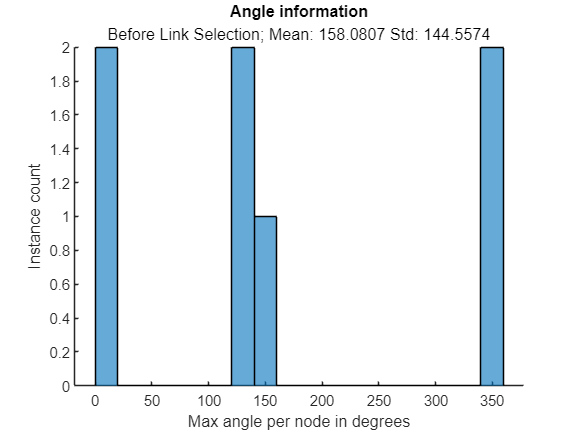

deg = 2.5714

before_mat_size =      7     7


Total distance measurements=3
------------------------------------------

after_deg = 2.5714

mat_size =      7     7


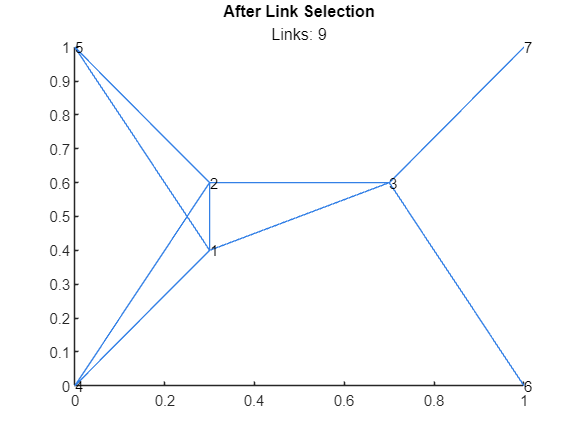

After Link Selection: Average node degree:2.5714

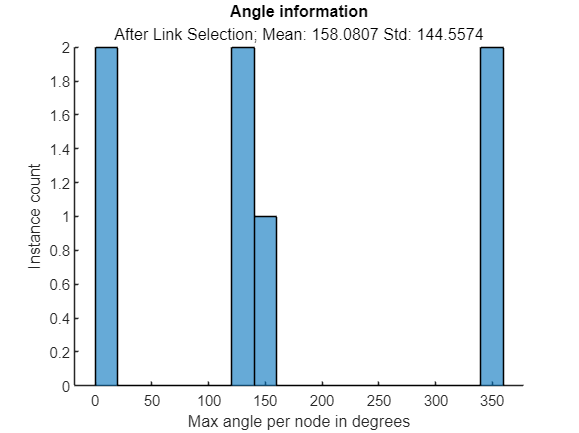

edges_before = 9

edges_after = 9

edges_reduction_percent = 0

## sDim = 2, noOfSensors = 3, noOfAnchors = 4
## pars: SDPsolver = sdpa, eps = 1.00e-05
## pars: sparseSW = 0, minDegree = 20, edgeSelectionSW = 1
## pars: objSW = 1, noisyFac = 8.3e-02, regTermFactor = 0.00
## the number of dist. eq. used in FSDP between two sensors  = 3
## the number of dist. eq. used in FSDP between a sensor & an anchor = 6
## the min., max. and ave. degrees over sensor nodes = 4, 4,   4.00
## elapsed time for generating an SDP relaxation problem =     0.13
-SeDuMi Wrapper for SDPA Start-
Converted to SDPA internal data / Starting SDPA main loop
Converting optimal solution to Sedumi format
-SeDuMi Wrapper for SDPA End-
## elapsed time for retrieving an optimal solution =     0.00
## elapsed time for SDP solver =     0.66
## mean error in dist. eq. = 1.83e-02, max. error in dist. eq. = 7.29e-02
## rmsd = 6.21e-02


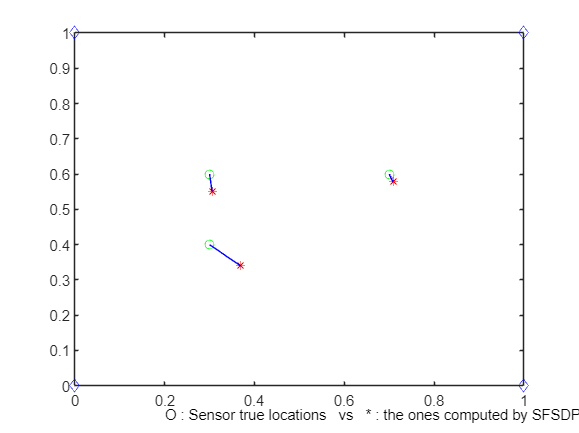

## see Figure 101
## elapsed time for a gradient method =     0.00
## mean error in dist. eq. = 2.27e-02, max. error in dist. eq. = 4.56e-02
## rmsd = 4.67e-02


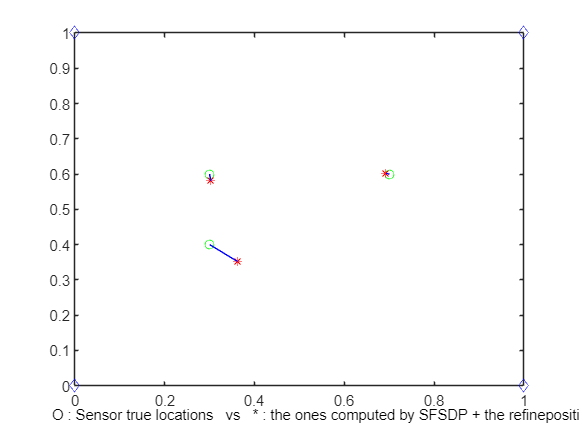

## see Figure 103


xMatrix0 = [0.3, 0.3, 0.7, 0,0,1,1;0.4,0.6,0.6,0,1,0,1];

sDim= 2; noOfSensors= 3; noOfAnchors= 4;
pars.free= 0; pars.eps= 1.0000e-05; pars.minDegree= 20; pars.objSW = 1;
pars.edgeAlgo="distance";
pars.edges_rand_state=0;
pars.plot=0;
pars.sparseSW = 0;
pars.analyzeData = 1;
pars.show_plots=0;
[xMatrix,info,pars,distanceMatrix,totalMeasurements,degreeList]=SFSDP(sDim,noOfSensors,...
 noOfAnchors,xMatrix0,distanceMatrix0,pars);

full(distanceMatrix)

ans =          0    0.2196    0.4147    0.5016    0.7566         0         0
         0         0    0.3562    0.6290    0.4713         0         0
         0         0         0         0         0    0.6471    0.4689


full(xMatrix)

ans =     0.3621    0.3025    0.6926         0         0    1.0000    1.0000
    0.3525    0.5809    0.6019         0    1.0000         0    1.0000


% load("RandLinkSelectionResults\S500A4RR0.15N0.05MMDeg5Runs2000.mat")
% [~,min_seed]=min(all_rmsds(1:end))
% [~,max_seed]=max(all_rmsds(1:end))
% 
% 
% measurement_error_var=0.05;
% dims=2;
% radio_range=0.35;
% num_sensors=500;
% num_anchors=16;
% anchor_layout_type=6;
% randomization_seed=144;
% minimum_degree=4;
% show_plots=1;
% edgeAlgo="distance"
% % edgeAlgo="onePhase"
% % edgeAlgo="twoPhase"
% % edgeAlgo="equalInterval"
% % edgeAlgo="original"
% % edgeAlgo="all"
% grad_only=0;
% 
% [rmsd,totalMeasurements]=test_FSDP(dims,measurement_error_var, ...
%     radio_range,num_sensors,anchor_layout_type,num_anchors, ...
%     randomization_seed,minimum_degree,show_plots,min_seed,edgeAlgo, ...
%     grad_only);

% rmsd=test_FSDP(dims,measurement_error_var,radio_range,num_sensors,anchor_layout_type,num_anchors,randomization_seed,minimum_degree,0,max_seed)

